# Matched Filters

## Matched Filters

Matched filters can be useful to determine whether a recieved signal is either the reflected signal with additive noise or just noise. This is useful in a radar system:

        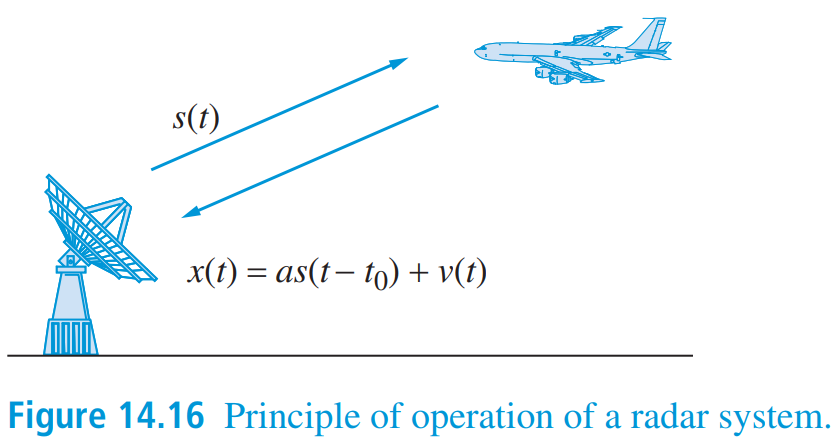

where

- $s\left(t\right)$ is a deterministic signal of known form

- $x\left(t\right)$ is the signal measured by the radar if an object is present

- $a$ is an attenuation factor  

- $t_0$ is the round-trip delay

- $v\left(t\right)$ is random noise

The measured signal $x\left(n\right)$ by the radar can be two things:

- If an object happens to be in the way then part of the signal is reflected plus noise

- If there is no object in the way of the transmitted pulse, the received signal is just noise

To help us determine whether an object is present, we pass the received signal into a $p-1$-tap FIR filter:

         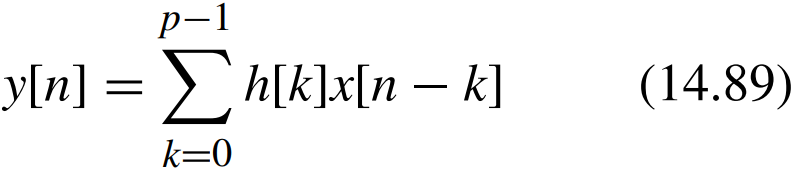

This figure shows what we are doing:

         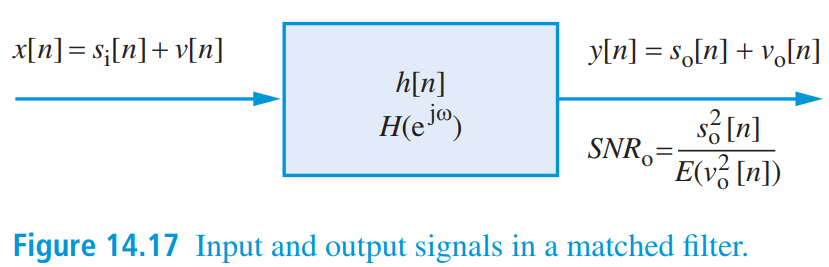

Our objective is to find the impulse $h\left\lbrack n\right\rbrack$ so that the output signal-to-noise ratio ${\mathrm{SNR}}_o$ is maximised:

        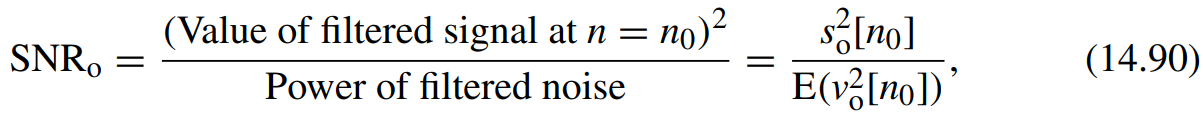

where $n_0 =p+D-1$

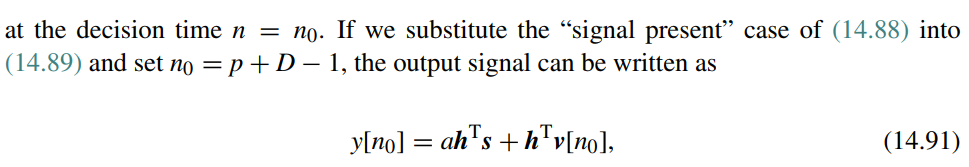

The solution is known as a *matched filter. *The impulse response of the optimum filter is

        

where 

        ${\mathit{\mathbf{R}}}_v$ is the autocorrelation matrix of the zero-mean wide-sense stationary noise $v\left\lbrack n\right\rbrack$

        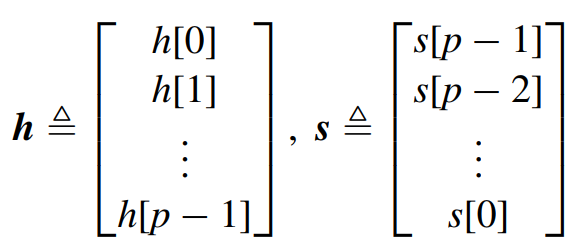

        $\kappa$ is a normalisation factor

Although the maximum SNR can be obtained by any choise of constant $\kappa$, we choose the constant by requiring that:

        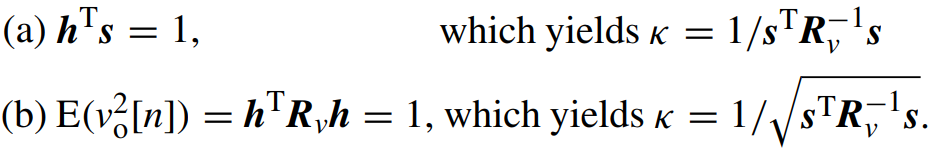

The maximum possible value of the output SNR is given by:

        

In summary, to design af matched filter we need two information:

- the autocorrelation sequence of the noise $r_{\mathrm{vv}} \left\lbrack \ell \right\rbrack$

- the transmitted signal $s\left\lbrack n\right\rbrack$

### Examples

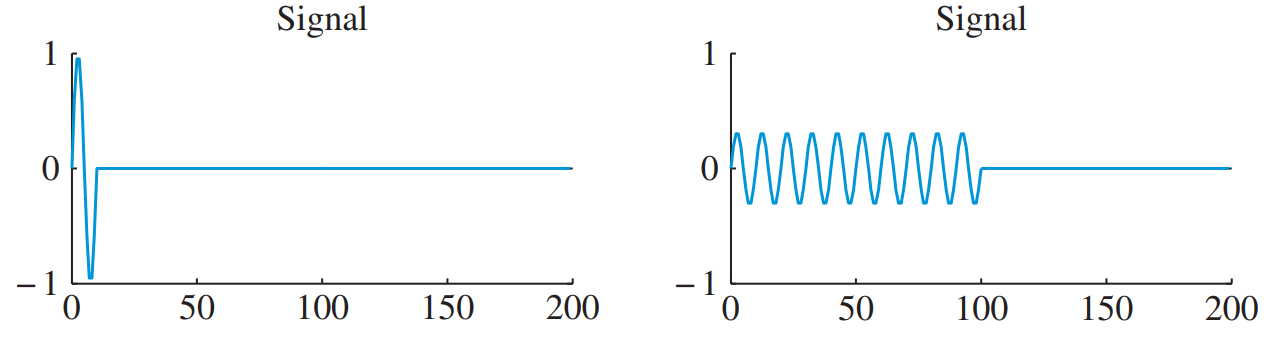

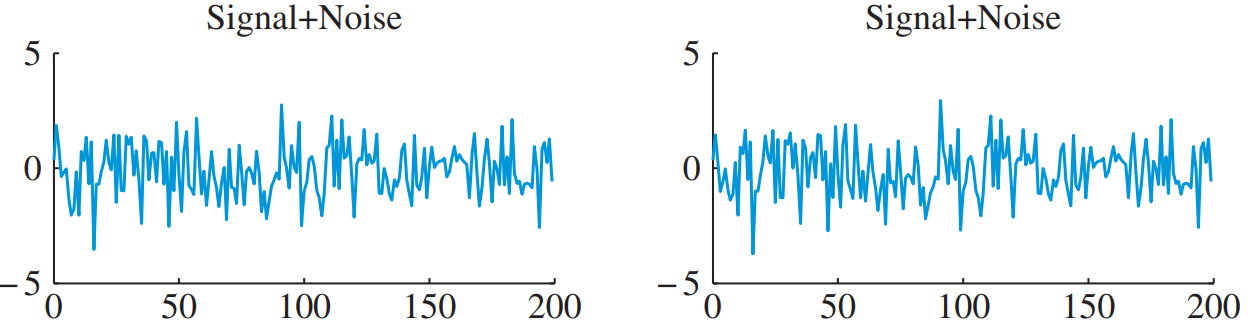

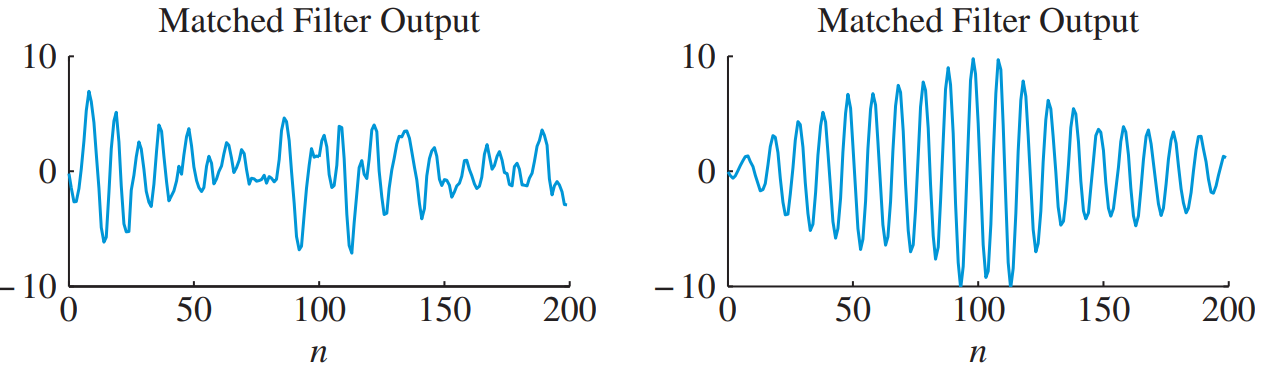

### White noise process

If the noise if white, then the autocorrelation matrix of white noise is ${\mathit{\mathbf{R}}}_v =\sigma_v^2 \mathit{\mathbf{I}}$. Then equations (14.97) and (14.98) are simplified to:

        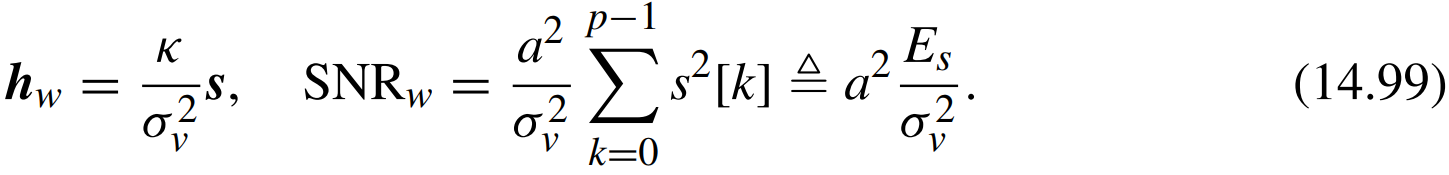

## **Problems**

### **QUIZ: **What is the assumption of the received signal?

The above model for $x\left(t\right)$ is sometimes a bit too simple. What assumptions have been made in the model?

- Does not take the Doppler effect into account.

- The signal could be reflected from different surfaces and not only by the plane

- Water particles in the air would scatter the signal (radar clutter)

### **QUIZ: How long should the matched filter be?**

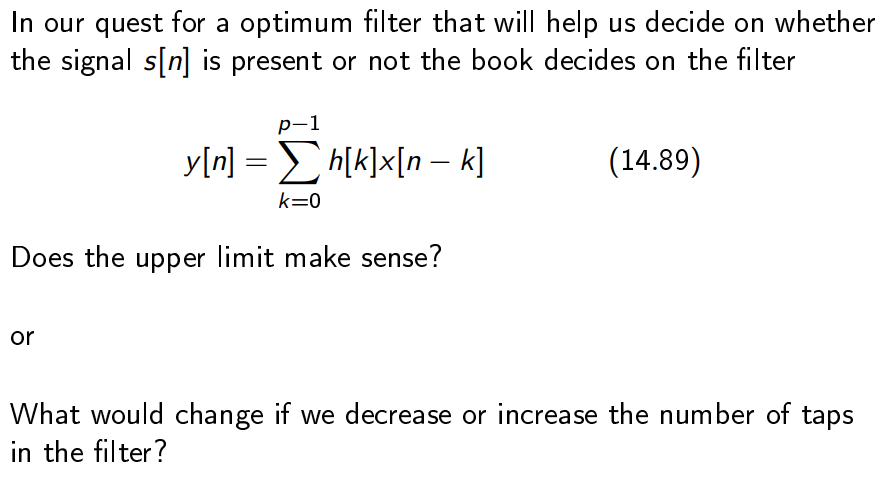

We want to use a filter that is as long as the signal itself.

### Quiz: Is it okay to choose a normalisation factor of 1

Is it okay to choose $\kappa =1$? Yes, because $\kappa$ is just a normalisation factor. We don't really care whether it is 1 or some other factor.

### **QUIZ:** How can we interpret in the frequency domain?

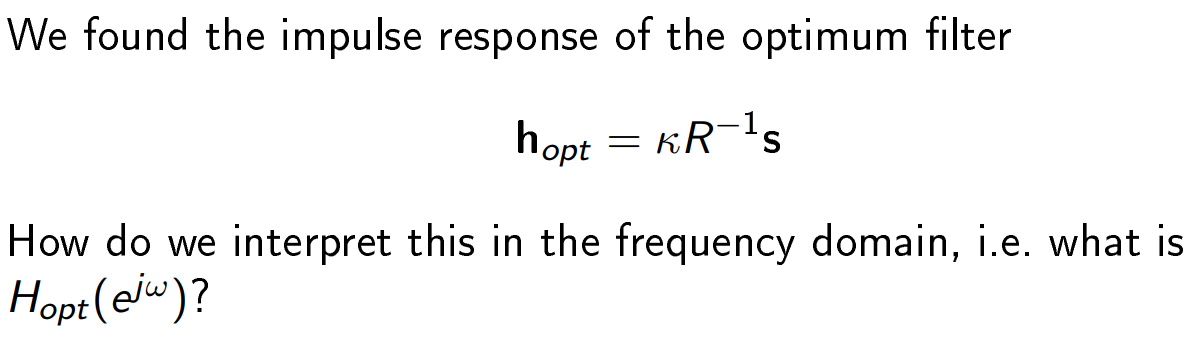

### True/False: Matched fiters are only applicable when the noise is white

The derivation of the matched filter makes no assumption of whether the noise is white or coloured. It should be noted though, that the interpretation of the filter is easier when the noise is white.

## ADSI Problem 6.1: Matched filters

Consider a deterministic signal that is only non-zero in the vicinity of *n*=0 as shown below and zero for all other values of $n$.

        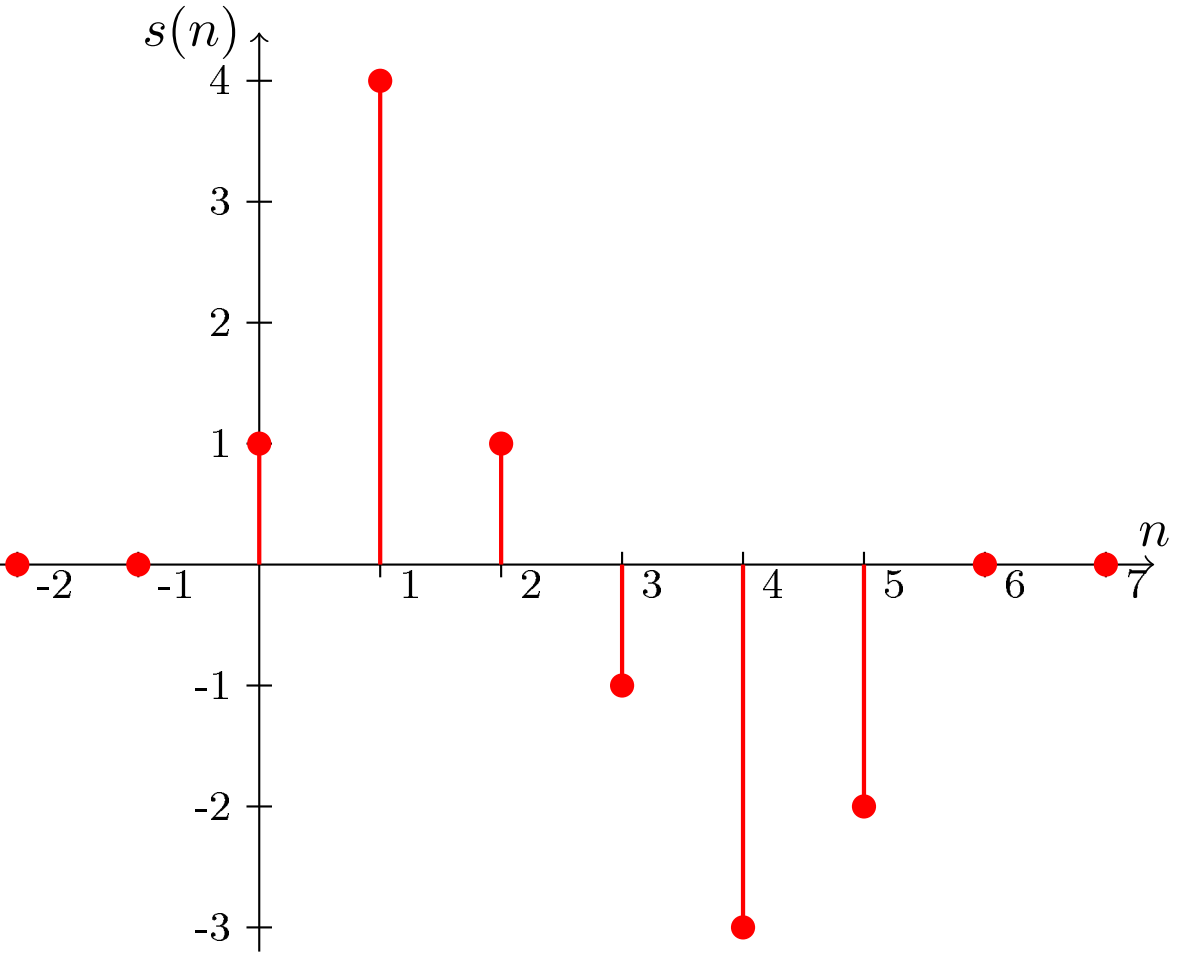

The signal is disturbed by additive noise from an AR(3) process given by

        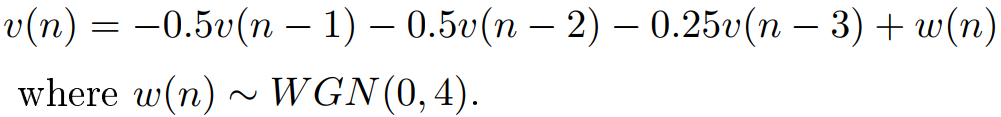

The goal of this problem is to construct a matched filter that can help us distinguish between the presence or absence of the signal in the noise.  

clear variables;

### 1) Plot a realisation of the signal with the added noise

*Create a realization of the noise and add the signal somewhere in the noise. Plot the result and comment on whether the signal is detectable.  *

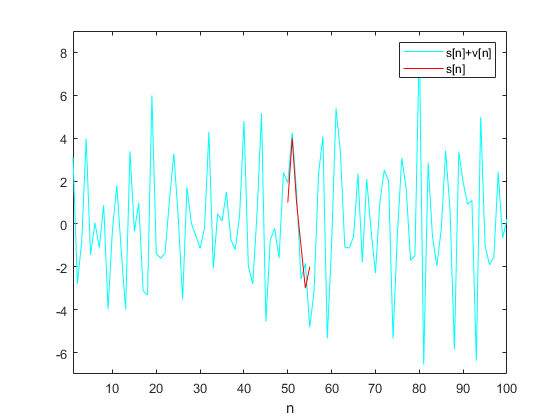

D = 50; % The place to embed signal into the noise

% Generate the deterministic signal s[n]
s = [1, 4, 1, -1, -3, -2]';

% Generate white noise w[n] with zero mean and variance 4
w_var = 4;
w = sqrt(w_var) * randn(10000, 1);

% Generate noise from an AR(3) process
b = 1;
a = [1, 0.5, 0.5, 0.25];
v = filter(b, a, w);

% Extract 100 samples to remove the transient effect 
% at the beginning and at the end of the filtered signal
x = v(500:600);

% Embed the signal s[n] in v[n] from D
s_in_x_start = D;
s_in_x_end =   D + length(s) - 1;
x(s_in_x_start:s_in_x_end) = x(s_in_x_start:s_in_x_end) + s; 

plot(1:length(x),       x, 'c', ...
     s_in_x_start:s_in_x_end, s, 'r') % the signal is completely invisible
legend('s[n]+v[n]', 's[n]')
xlabel('n')
xlim([1,100])
ylim([-7, 9])

The signal is cannot be distinguished from the noise.

### 2) Plot the power density spectrum of the noise and spectrum of the signal

*Plot the power density spectrum of the noise and spectrum of the signal, see Eq. (14.91).  *

The noise is generated by an AR(3) process plus some white Gaussian noise:

        

We can determine the Power Density Spectrum of an ARMA(p,q) process is given by

        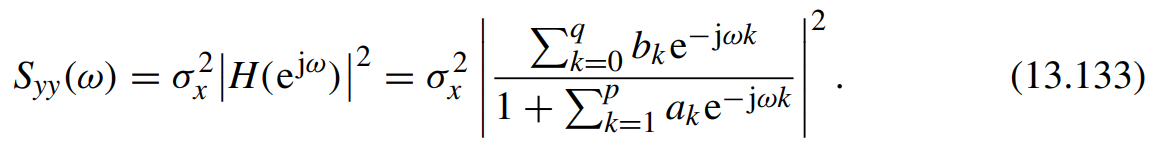

The power spectrum of an AR(p) process is given by:

        
$$S_{\mathrm{yy}} \left(\omega \right)=\sigma_x^2 {\left|\frac{1}{1+\sum_{k=1}^p a_k e^{-j\omega k} }\right|}^2$$


For this problem, we have:

        
$$S_{\mathrm{vv}} \left(\omega \right)=4{\left|\frac{1}{1+0\ldotp 5e^{-j\omega } +0\ldotp 5e^{-\mathrm{j2}\omega } +0\ldotp 25e^{-\mathrm{j3}\omega } }\right|}^2$$


The algorithm is as follows:

- Use the coefficents $\left\lbrace a_1 ,a_2 ,\cdots ,a_p \right\rbrace$ for the$\mathrm{AR}\left(p\right)$ model, 

- Compute the transfer function for the $\mathrm{AR}\left(p\right)$ by computing the sum and finding its reciprocal

- Compute the conjugate of the transfer function: ${\left|H\left(e^{j\omega } \right)\right|}^2$

- Multiply it with the variance $\sigma_x^2$

The algorithm is implemented in the functions `ar2psd()` function:

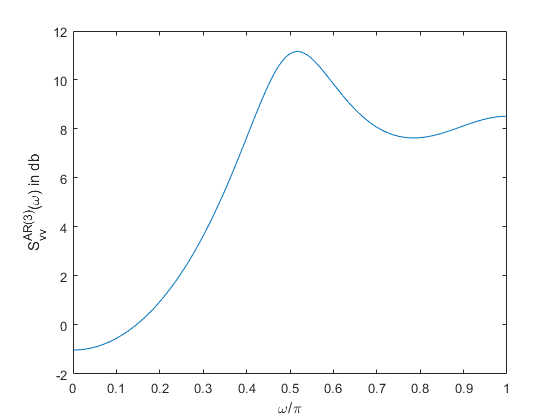

N = 256;

a = [0.5, 0.5, 0.25]; % The coefficients of the AR(3) model
w_var = 4; % The variance of white noise
[S_vv, w] = ar2psd(a, w_var, N); % Compute the PSD of AR(3) model

plot(w/pi, pow2db(S_vv))
xlabel('\omega/\pi')
ylabel('S_{vv}^{AR(3)}(\omega) in db')

We can plot the spectrum of the signal $s\left(n\right)$ using the `freqz()` function:

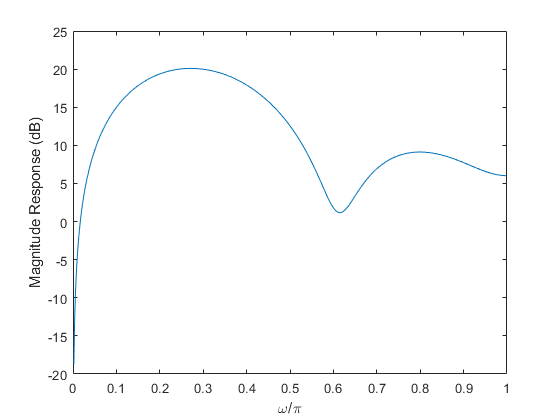

[H,w2] = freqz(s, 1);
plot(w2/pi, 20*log10(abs(H)))
xlabel('\omega/\pi')
ylabel('Magnitude Response (dB)')

### 3) Calculate the matched filter

*Calculate the matched filter, the frequency response of the matched filter and the optimum signal to noise ratio. You can use *`xcorr`* on the noise realization to find *${\mathit{\mathbf{R}}}_v$*.  *

The impulse response of the matched filter is given by:

        

where $k$ is the normalisation factor. Although the maximum SNR can be obtained by any choise of constant $\kappa$, we choose the constant by requiring that:

        

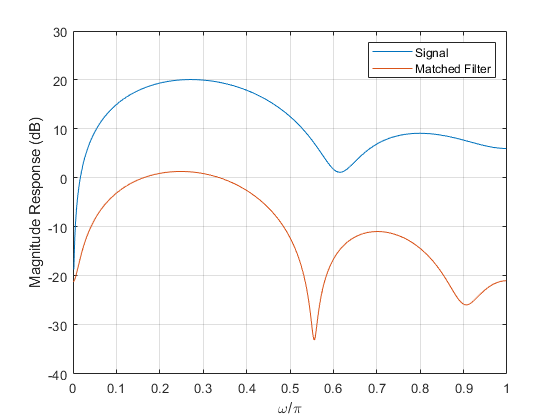

p = numel(s); % Signal length

% The autocorrelation matrix must be p x p since
% its inverse is multiplied by a p-tap signal s(n)
[r_vv, ~] = xcorr(v, p-1, 'biased');
R_vv = toeplitz(r_vv(p:end));

% Compute normalisation factor
k = 1/sqrt(s'*(R_vv\s)); % Same as 1/sqrt(s'*inv(R_vv)*s)

% Compute the filter
h = k*(R_vv\s); % Same as k*inv(R_vv)*s

[H_s, w_s] = freqz(s, 1);
[H_h, w_h] = freqz(h, 1);
plot(w_s/pi, 20*log10(abs(H_s)), w_h/pi, 20*log10(abs(H_h)))
legend('Signal', 'Matched Filter')
xlabel('\omega/\pi')
ylabel('Magnitude Response (dB)')
grid on;

The maximum possible value of the output SNR is given by:

        

Since the attenuation factor $a$ is not given in this problem, we assume that it is 1:

a = 1;
SNR = a^2 * s' * (R_vv\s)

SNR = 11.0394

### [?] 4) Does the frequency response of the matched filter make sense?

*Does the frequency response of the matched filter make sense seen in relation with the spectra from question 2?  *

In question 2) we found that the AR(3) noise model has peak power at 0.5.

        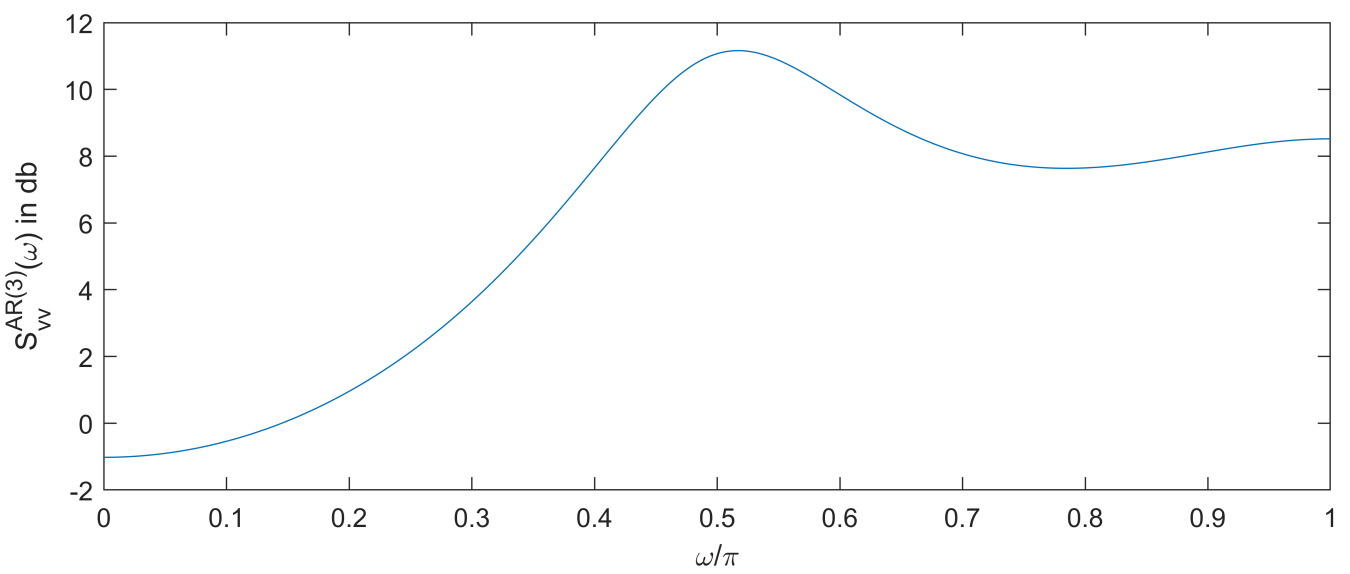

Looking at the frequency response of the signal, we observe that it peaks around 0.25 and dips around 20 dB at around 0.6. 

The frequency response of the matched filter shows that it is minimising the noise in the region at around 0.55. The noise power peaks at around 0.5

        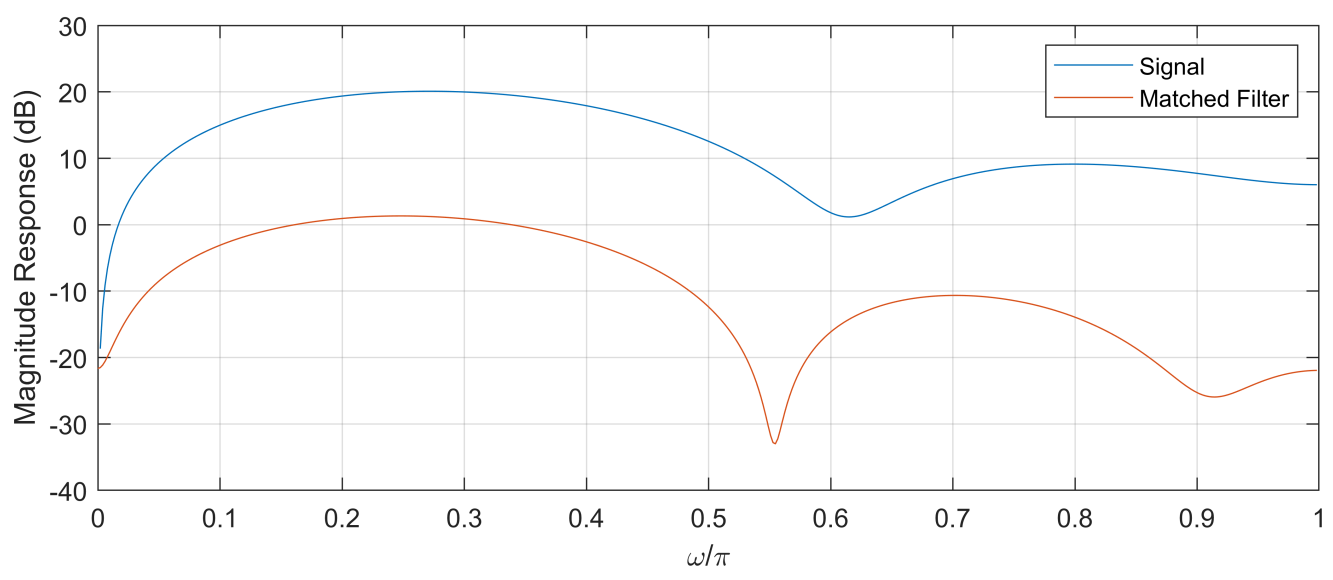

### [✔] 5) How efficient is the matched filter?

*Plot the signal before and after the matched filter as well as the square of the output of the matched filter on the same graph and comment on the effiency of the matched filter in our quest to detect the presence of the signal.  *

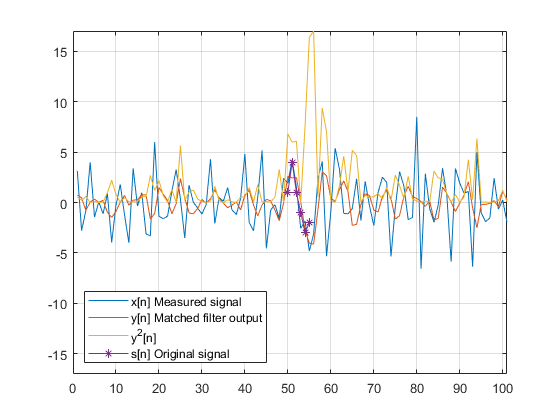

% x(n) is the 100 samples extracted from the noise signal v(n)
% y(n) is the result of feeding x(n) to the matched filter
y = filter(h, 1, x);
y_squared = y.^2;

n = 1:length(x);

n2 = s_in_x_start:s_in_x_end;
xs = s;

plot(n,x, n,y, n,y_squared,  n2,xs,'*-')
xlim([0, numel(n)])
ylim([-max(y_squared), max(y_squared)])
legend({'x[n] Measured signal', 'y[n] Matched filter output', 'y^2[n]', 's[n] Original signal'}, ...
    'Location','southwest')

grid on;

It's close to impossible to find the orignal signal $s\left\lbrack n\right\rbrack$ in the measured signal $x\left\lbrack n\right\rbrack$. It is also difficult to detect $s\left\lbrack n\right\rbrack$ after filtering $x\left\lbrack n\right\rbrack$ with the matched filter i.e.,$y\left\lbrack n\right\rbrack$. It is easier to detect the original signal in the square of the output of the matched filter $y^2 \left\lbrack n\right\rbrack$. Running the code multiple times i.e., creating different realisations of the noise, we may see many false positives. The figure below shows an example of this. The highest response is measured at $n=6$ but we know that the signal is embedded in $n=50$.

        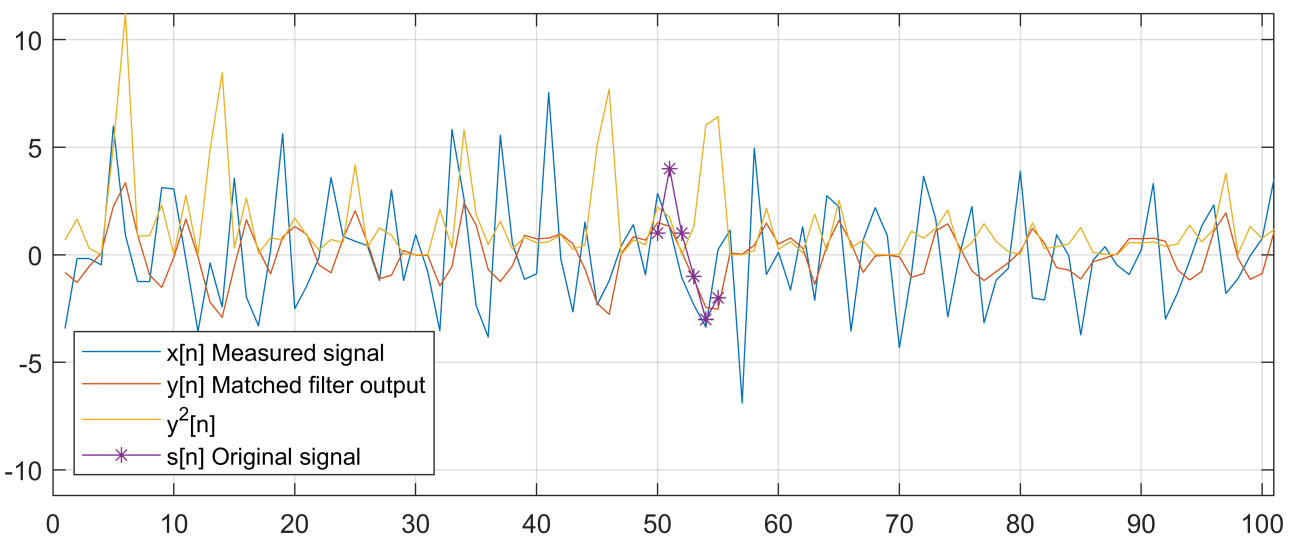

### [✔] 6) What happens to the optimum SNR when the noise is twice as powerful?

*Is the optimum signal to noise ratio halved if the AR(3) is instead driven by twice as powerful white noise, i.e. w(n) ∼ WGN(0,8)? Why or why not?*  

We will compute the SNR again but this time with $\sigma_w^2 =8$:

        

% Generate white noise w[n] with zero mean and variance 8
w2_var = 8;
w2 = sqrt(w2_var) * randn(10000, 1);

% Put the white noise through an AR(3) process
b = 1;
a = [1, 0.5, 0.5, 0.25];
v2 = filter(b, a, w2);

% Extract 100 samples to remove the transient effect 
% at the beginning and at the end of the filtered signal
x2 = v2(500:600);

p = numel(s); % Signal length

% The autocorrelation matrix must be MxM since
% its inverse is multiplied by a M-tap signal s(n)
[r_vv2, lags] = xcorr(x2, p-1, 'biased');
R_vv2 = toeplitz(r_vv2(p:end));

a = 1;
SNR2 = a^2 * s' * (R_vv2\s)

SNR2 = 7.3950

SNR2/SNR

ans = 0.6699

The optimal signal-to-noise-ratio is almost halved when the white noise is doubled. The reduction of SNR is not always decreased by a factor of though. Although the noise power is doubled, the shape of the optimum filter will change because it depends on the measured signal:

        

### [✔] 7) Compute SNR using a 6-tap moving average filter

*Assume that instead of the matched filter a simple 6-tap moving average filter is used instead. That is*

        
$$\mathit{\mathbf{h}}={\left\lbrack \begin{array}{cccccc}
\frac{1}{6} & \frac{1}{6} & \frac{1}{6} & \frac{1}{6} & \frac{1}{6} & \frac{1}{6}
\end{array}\right\rbrack }^T$$


*Calculate the signal to noise ratio when the moving average filter is used.*

We can compute the SNR using the following formula:

        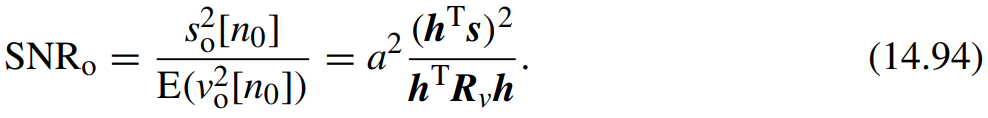

% h_avg = [1, 0, 1, 1, 1, 1]'./5;
h_avg = [1, 1, 1, 1, 1, 1]'./6;
a = 1;
SNR_avg = a^2 * (h_avg'*s)^2 / (h_avg'*R_vv*h_avg)

SNR_avg = 0

The SNR of the moving average filter is zero (or a number very close to zero). The moving average filter gives us the average of a signal. Since the original signal has zero mean, the average is zero. This is not surprising. If we change the filter, then the SNR is no longer zero.

h4 = [1, 0, 1, 1, 1, 1]'./5;
a = 1;
SNR4 = a^2 * (h4'*s)^2 / (h4'*R_vv*h4)

SNR4 = 1.4292

## Problem 14.14: Matched filters, compare short vs long signals

clear variables;

*In this problem we discuss in detail the matched filtering problem illustrated in Figure 14.18.*

**Figure 14.18 **shows the operation of a matched filter in white noise. 

The two signals have different lengths ($p=10$ and $p=100$, respectively) but the same energy.

        

        

Notice that the peak response of the matched filter occurs at $n_0 =p-1$ because there is no time delay i.e. $D=0$. Normally, the output SNR is maximised at time $n_0 =p+D-1$. In practice, finding the time delay $D$ depends on the particular application.

        

*The input to the matched filter is given by*

        
$$x\left\lbrack n\right\rbrack =s_I \left\lbrack n\right\rbrack +v\left\lbrack n\right\rbrack =a\;s\left\lbrack n-D\right\rbrack +v\left\lbrack n\right\rbrack$$


where

- $a$ is the attenuation factor  

- $D$ is the round-trip delay

- $v\left\lbrack n\right\rbrack$ is the white Gaussian noise with zero mean and unit variance

- $s_I \left\lbrack n\right\rbrack =0$ outside the interval $0\le n\le p-1$

### **1) ***Explain why, in the absence of noise, the output is the ACRS of the desired signal.*

In case of white noise, the impulse response of the matched filter $h\left\lbrack n\right\rbrack$ is equal to the signal that we want to detect $s_I \left\lbrack n\right\rbrack$. As such the output of the matched filter is the same as autocorrelation:

### 2) Determine the matched filter of a short cosine signal

*Suppose that *$p=10$*  and *$s_i \left\lbrack n\right\rbrack =\mathrm{cos}\left(2\pi \frac{n}{10}\right)$*. Generate *$N=200$* samples of the noisy signal *$s\left\lbrack n\right\rbrack$* and process it through the matched filter designed for *$s_i \left\lbrack n\right\rbrack$*. Plot the desired, input, and filtered signals and determine when the matched filter output is output.*

The impulse response of the matched filter is given by:

        

where $k$ is the normalisation factor and ${\mathit{\mathbf{R}}}_v$ is the autocorrelation matrix of the noise. 

The output SNR can be computed using the formula:

        

The computation is coded in a MATLAB function named `matched_filter` (see the end of the document)

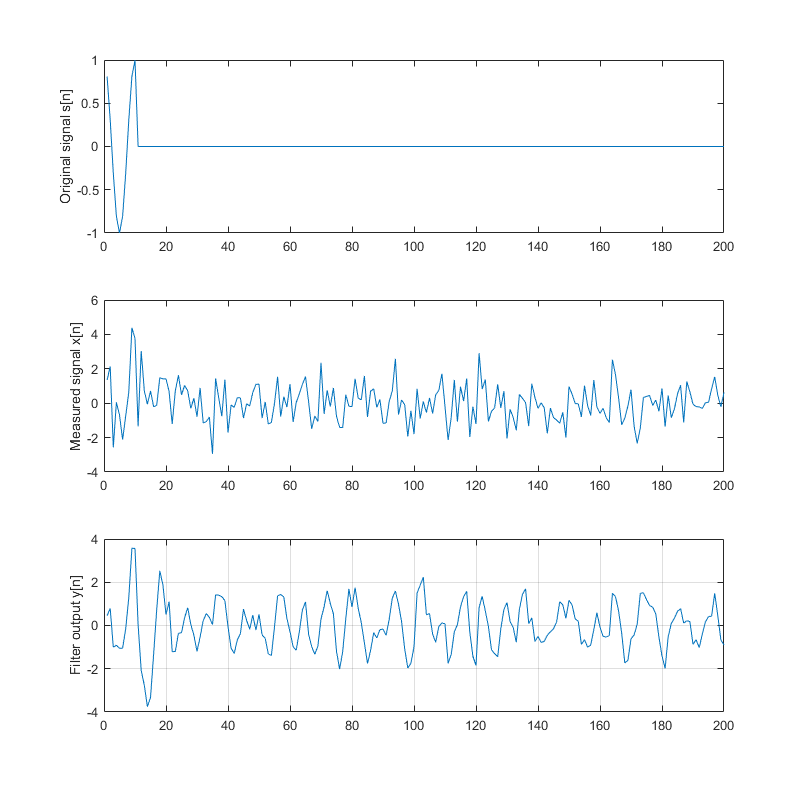

N = 200;
n = (1:N)';

p = 10; % Signal length

% Generate the attenuated signal.
% Ensure that s[n] is zero when n is outside the interval [1, p]
s = zeros(N, 1);
inside_indices = (n >= 1 & n <= p);
s(inside_indices) = cos(2*pi*n(inside_indices)/10);

% Generate the zero-mean WGN with unit variance
v = randn(N, 1);

% Generate the measured signal x[n]
x = v + s;

% Compute the impulse response of the matched filter
[h, SNR] = matched_filter(s(1:p), v);

% Feed the measured signal to the matched filter
y = filter(h, 1, x);

figure('position', [0, 0, 800, 800])
subplot(3,1,1); plot(n,s); ylabel('Original signal s[n]')
subplot(3,1,2); plot(n,x); ylabel('Measured signal x[n]')
subplot(3,1,3); plot(n,y); ylabel('Filter output y[n]')
xlim([0 N])
grid on;

clear figure;

From the filtered output, it is difficult to determine where the original signal is placed. 

### 3) Determine the matched filter of a long cosine signal

*Repeat 2) for  *$p=100$*  and *$s_i \left\lbrack n\right\rbrack =\frac{1}{\sqrt{10}}\cos \left(2\pi \frac{n}{10}\right)$*.*

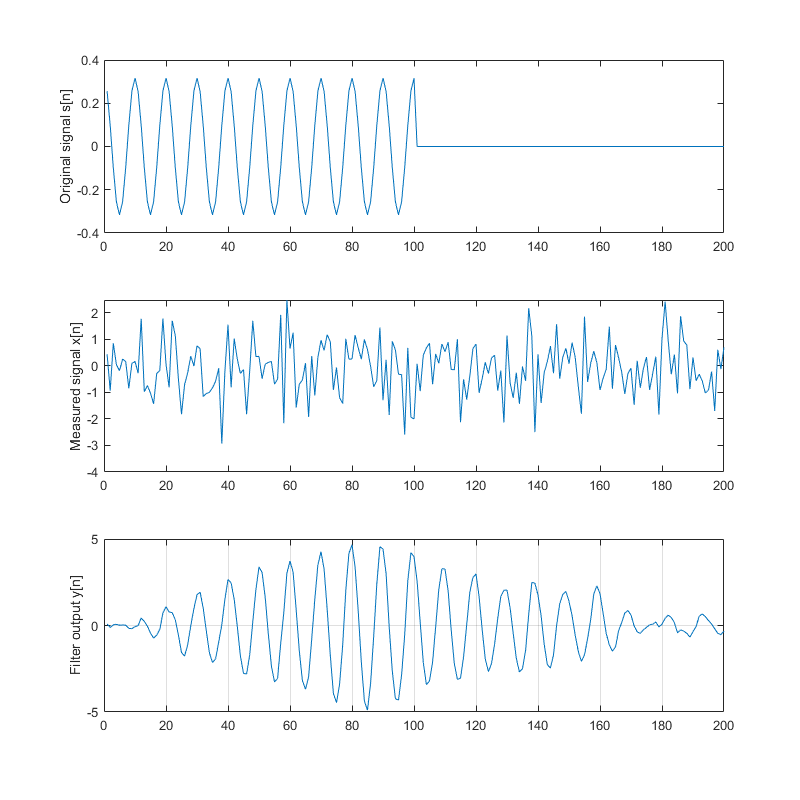

p = 100; % Signal length

% Generate the attenuated signal.
% Ensure that s[n] is zero when n is outside the interval [1, p]
s = zeros(N, 1);
inside_indices = (n >= 1 & n <= p);
s(inside_indices) = (1/sqrt(10)) * cos(2*pi*n(inside_indices)/10);

% Generate the zero-mean WGN with unit variance
v = randn(N, 1);

% Generate the measured signal x[n]
x = v + s;

% Compute the impulse response of the matched filter
[h_100, SNR_100] = matched_filter(s(1:p), v);

% Feed the measured signal to the matched filter
y = filter(h_100, 1, x);

figure('position', [0, 0, 800, 800])
subplot(3,1,1); plot(n,s); ylabel('Original signal s[n]')
subplot(3,1,2); plot(n,x); ylabel('Measured signal x[n]')
subplot(3,1,3); plot(n,y); ylabel('Filter output y[n]')
xlim([0 N])
grid on;

clear figure;

### 4) Which signal can be detected more easily by visual inspection?

*Which signal can be detected more easily by visual inspection of the matched filter output? Is this justified by comparing the output SNR in each case?  *

For certain noise realisations, it is easier to detect the second (longer) signal by visual inspect than the first signal. However, running the code multiple times i.e., creating different realisations of the noise, we may see many false positives. The figure below shows an example of this. The highest response is measured at $n=140$ but the maximum filter response should occur at $n=p+D-1=100+0-1=99$.

        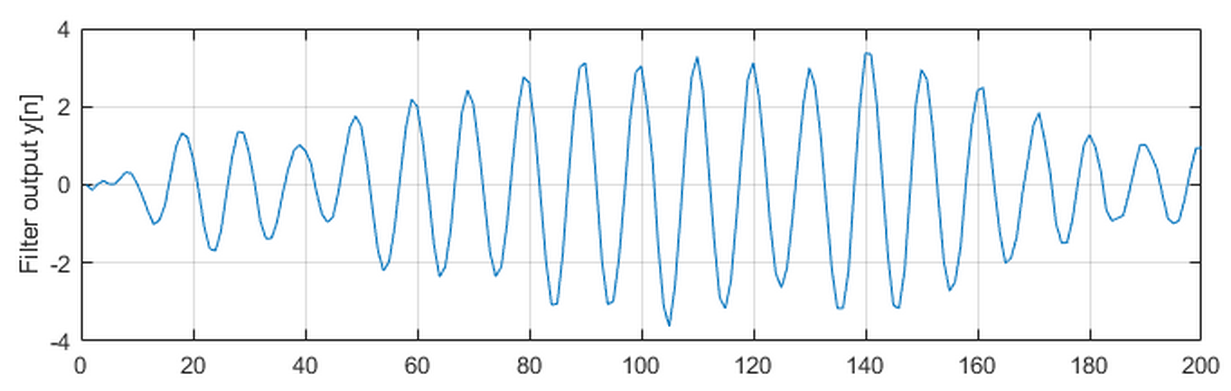

Comparing the output SNR of the two filters, we observe that the SNR of the longer filter is usually better but this is not always the case. Different realisation of the noise process, yields different results:

SNR

SNR = 3.9127

SNR_100

SNR_100 = 10.1572

## Problem 14.35: Matched Filter and white noise

In the book on page 861, the authors claim: "*The term matched filter was introduced because, in the case of white noise, the impulse response is “matched” to the shape of the signal being sought. In fact, the output of the matched filter is proportional to the correlation between the signal segment stored in the filter memory and the signal of interest.*"

This problem investigates this claim.

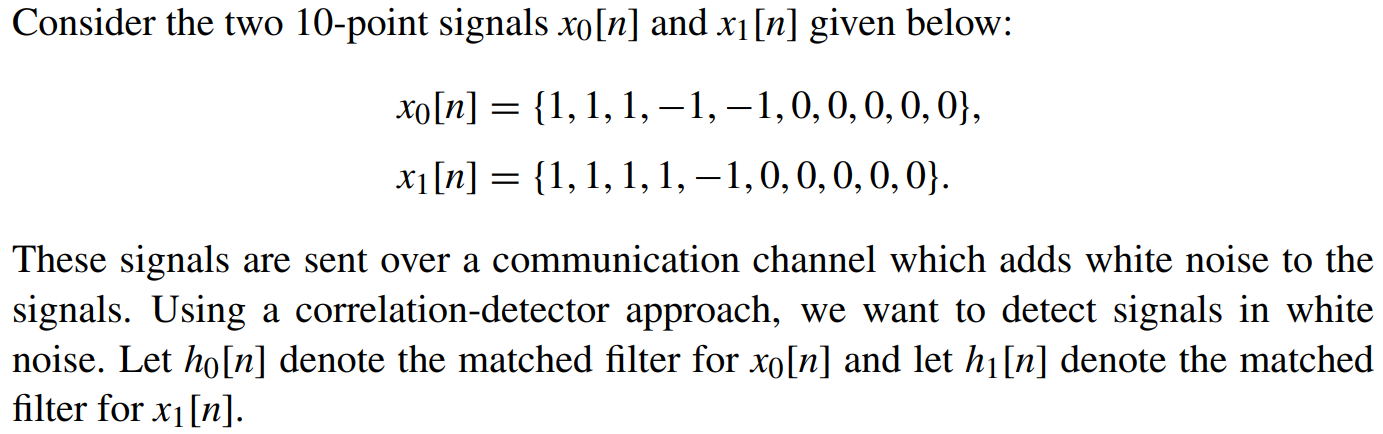

clear variables;

### [👀] a) Compare the impulse responses with input signals

I don't understand what should be done here!

x0 = [1, 1, 1, -1, -1, 0, 0, 0, 0, 0]';
x1 = [1, 1, 1,  1, -1, 0, 0, 0, 0, 0]';

N = 20; n = 1:N;
v=zeros(N,1);%randn(N,1);
w0 = v + [x0;zeros(N-length(x0),1)];
w1 = v + [x1;zeros(N-length(x1),1)];
h0 = flip(x0); %wgn -> just use flipped
h1 = flip(x1);
figure
subplot(2,2,1); stem(filter(h0,1,w0)); ylabel('h0*w0')
subplot(2,2,2); stem(filter(h0,1,w1)); ylabel('h0*w1')
subplot(2,2,3); stem(filter(h1,1,w0)); ylabel('h1*w0')
subplot(2,2,4); stem(filter(h1,1,w1)); ylabel('h1*w1')

### b) Compute the correlation of input and impulse response

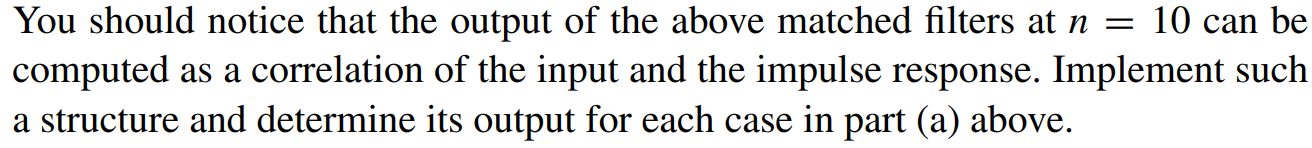

### c) Modify the signals so the relations are zero

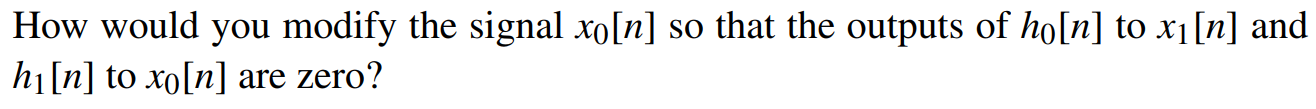

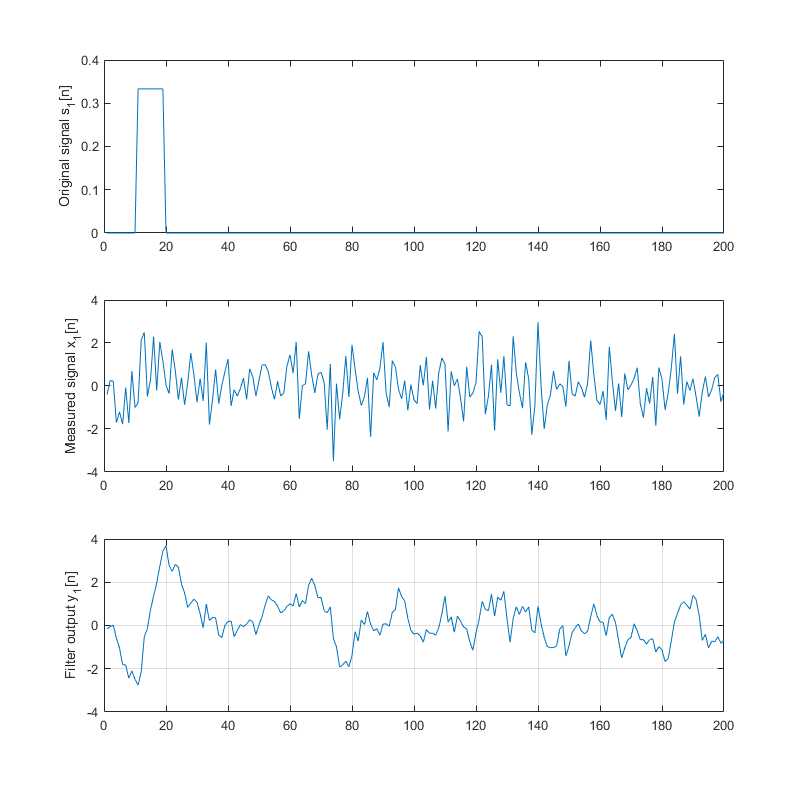

% Don't understand what is going on here
x0 = flip(x1); % the inverse, maybe?
corr(x0,x1)
w0 = v + [x0;zeros(N-length(x0),1)];
h0 = flip(x0); %wgn -> just use flipped
figure

subplot(2,2,1); stem(filter(h0,1,w0)); ylabel('h0*w0')
subplot(2,2,2); stem(filter(h0,1,w1)); ylabel('h0*w1')
subplot(2,2,3); stem(filter(h1,1,w0)); ylabel('h1*w0')
subplot(2,2,4); stem(filter(h1,1,w1)); ylabel('h1*w1')

## Problem 14.37: Matched Filter and Square Pulse Signals 

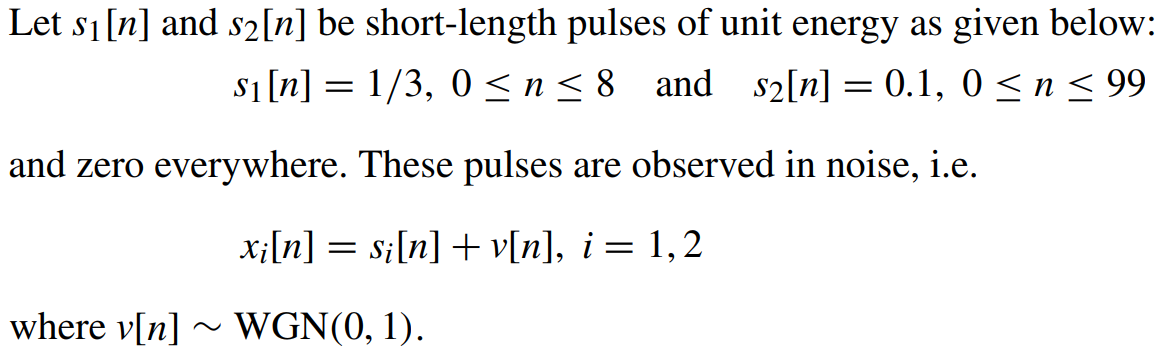

clear variables;

### a)  Process x1[n] through a matched filter

*Generate 200 samples of the noisy x1[n] signal and process it through the matched filter designed for s1[n]. Plot the original, noisy, and filtered signals and determine when the matched filter output is maximum.*

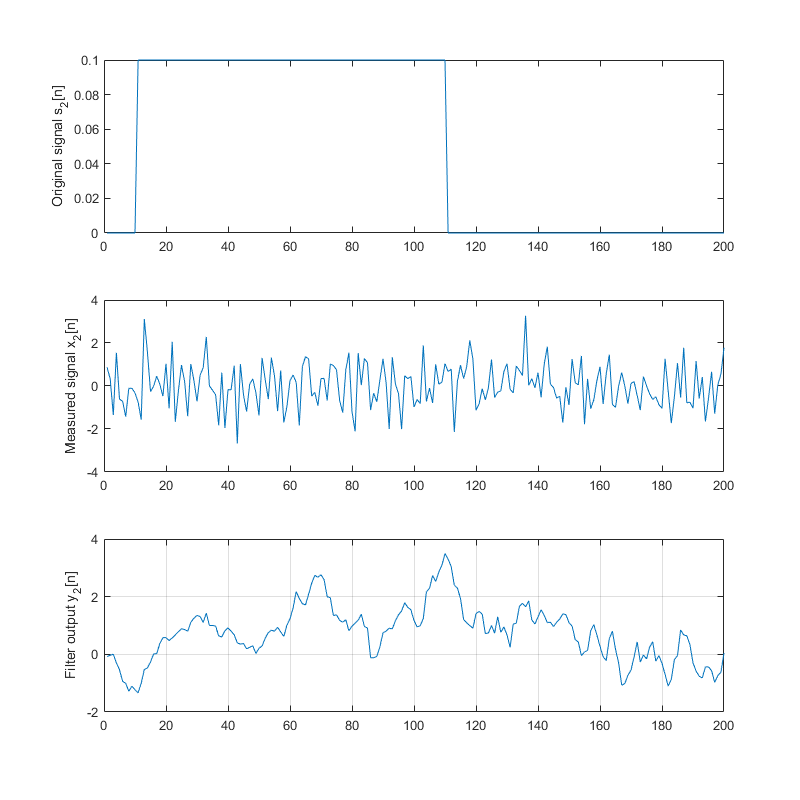

s1 = 1/3*ones(9, 1);

N = 200;
n = 1:N;
noise_var = 1;
D = 10;
[x1, v1, s1e] = gen_noisy_signal(s1, N, noise_var, D);

% Compute the impulse response of the matched filter
[h1, SNR1] = matched_filter(s1, v1);

% Feed the measured signal to the matched filter
y1 = filter(h1, 1, x1);

figure('position', [0, 0, 800, 800])
subplot(3,1,1); plot(n, s1e); ylabel('Original signal s_1[n]')
subplot(3,1,2); plot(n, x1); ylabel('Measured signal x_1[n]')
subplot(3,1,3); plot(n, y1); ylabel('Filter output y_1[n]')

xlim([0 N])
grid on;

### b)  Process x2[n] through a matched filter

*Generate 200 samples of the noisy x2[n] signal and process it through the matched filter designed for s2[n]. Plot the original, noisy, and filtered signals and determine when the matched filter output is maximum.*

  

s2 = 0.1*ones(100, 1);

peak_n1 = 20

peak_n2 = 110

N = 200;
n = 1:N;
noise_var = 1;
D = 10;

SNR1 = 1.3087

[x2, v2, s2e] = gen_noisy_signal(s2, N, noise_var, D);

SNR2 = 2.2533


% Compute the impulse response of the matched filter
[h2, SNR2] = matched_filter(s2, v2);

% Feed the measured signal to the matched filter
y2 = filter(h2, 1, x1);

figure('position', [0, 0, 800, 800])
subplot(3,1,1); plot(n, s2e); ylabel('Original signal s_2[n]')
subplot(3,1,2); plot(n, x2); ylabel('Measured signal x_2[n]')
subplot(3,1,3); plot(n, y2); ylabel('Filter output y_2[n]')
xlim([0 N])
grid on;

### c) Discuss the results in (a) and (b)

*Discuss your results in (a) and (b) above in terms of filtered waveforms and maximization of the output SNR.  *

The peak response of the matched filter should occur at $n_0 =p+D-1$ 

Since $s_1 \left\lbrack n\right\rbrack$ is a 10-tap signal, this point should be $n_0 =10+10-1=19$

Since $s_2 \left\lbrack n\right\rbrack$ is a 100-tap signal, this point should be $n_0 =100+10-1=119$

We rarely see these points for different realisations of the noise process. 

[~, peak_n1] = max(y1)
[~, peak_n2] = max(y2)

*What can we conclude?*

SNR1
SNR2

## Exam 2017 Problem 3: Detect presence of signal using matched filter

Consider the deterministic signal, *s*(*n*) shown below in blue. The signal is zero for all other values of  *n*.  

        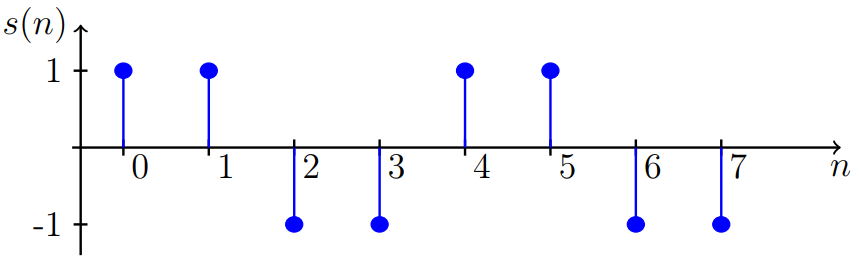

The signal is distorted by additive low frequency noise with autocorrelation $r_v \left(\ell \right)=0\ldotp 4^{|\ell |}$.

clear variables;

### 1) Design a matched filter and determine the improvement in SNR  

*Design a matched filter for detecting the presence of the signal and determine the improvement in signal to noise ratio. *

The impulse response of the matched filter is given by:

        

where $R_v$ is autocorrelation matrix of noise and $\kappa$ is the normalisation factor. 

Although the maximum SNR can be obtained by any choise of constant $\kappa$, we choose the constant by requiring that:

        

s = [1, 1, -1, -1, 1, 1, -1, -1]';

p = numel(s); % Signal length

% The autocorrelation matrix must be p x p since
% its inverse is multiplied by a p-tap signal s(n)
ell = 0:p-1;
r_vv = 0.4.^ell;
R_vv = toeplitz(r_vv);

% Compute normalisation factor (b)
k = 1/(s'*(R_vv\s));       % Using (a)

h =     0.0735
    0.1422
   -0.1422
   -0.1422
    0.1422
    0.1422
   -0.1422
   -0.0735


% k = 1/sqrt(s'*(R_vv\s)); % Using (b)

% Compute the filter
h = k*(R_vv\s); % Same as k*inv(R_vv)*s

SNR_i = 1


% Print the matched filter coefficients
h

The SNR at the input is given by:

        
$${\textrm{SNR}}_i =\frac{\mathrm{power}\;\mathrm{of}\;\mathrm{signal}}{\textrm{power}\;\textrm{of}\;\textrm{noise}}=\frac{s^2 \left(n=n_0 \right)}{r_v \left(0\right)}$$


SNR_i = s(1)^2/r_vv(1)

The optimum SNR at the output is given by:

        

Assuming the attenuation factor $a=1$:

a = 1;

SNR_o = 9.7143

SNR_o = a^2 * s' * (R_vv\s)

The improvement in SNR is 9.7 (almost 10 times)

### 2) Discuss the improvement of SNR if a high-frequency signal is used

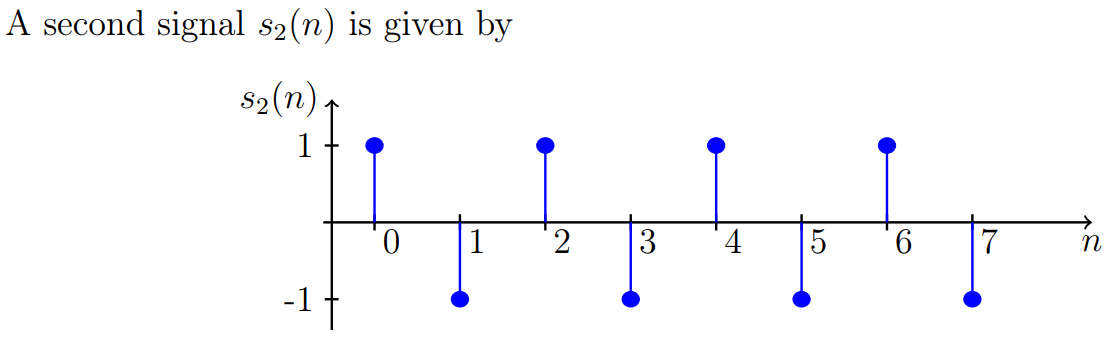

If we use $s_2 \left(n\right)$ instead of $s\left(n\right)$, the output SNR becomes 17.3:

s = [1, -1, 1, -1, 1, -1, 1, -1]';
p = numel(s); % Signal length
ell = 0:p-1;
r_vv = 0.4.^ell;
R_vv = toeplitz(r_vv);
a = 1;
SNR_o = a^2 * s' * (R_vv\s)

SNR_o = 17.3333

The $s_2 \left(n\right)$ is similar to $s\left(n\right)$ but it oscillates faster i.e., has higher frequency than the $s\left(n\right)$ signal. Since the noise is at low frequency, it is easier to separate the $s_2 \left(n\right)$ signal from the noise. This means that a higher SNR can be expected from a signal with a higher frequency.

That is why the output SNR for $s_2 \left(n\right)$ is better than that for $s\left(n\right)$.

## Exam 2018 Problem 3: Improve SNR with a matched filter

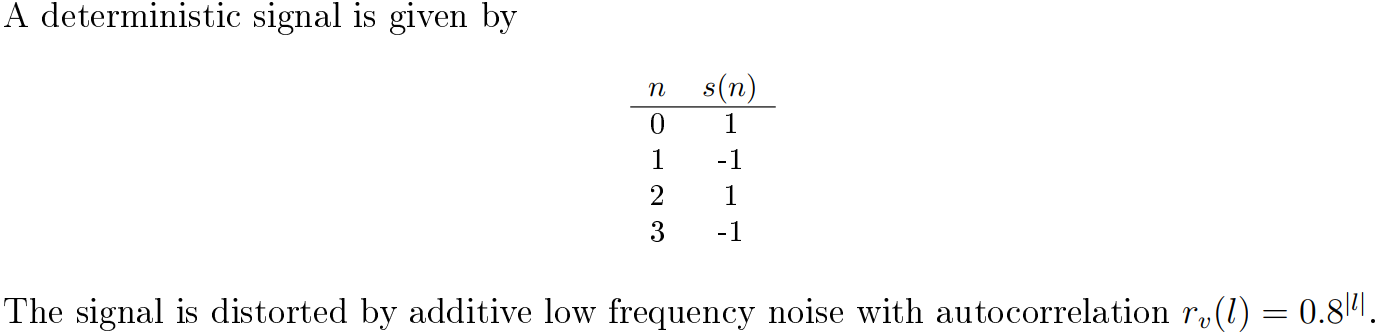

clear variables;

### 1) Design a matched filter to improve the SNR

*Design a matched filter to improve the signal to noise ratio and comment on the improvement.  *

The impulse response of the matched filter is given by:

        

where $R_v$ is autocorrelation matrix of noise and $\kappa$ is the normalisation factor. 

Although the maximum SNR can be obtained by any choise of constant $\kappa$, we choose the constant by requiring that:

        

s = [1, -1, 1, -1]';

p = numel(s); % Signal length

% The autocorrelation matrix must be p x p since
% its inverse is multiplied by a p-tap signal s(n)
ell = 0:p-1;
r_vv = 0.8.^ell;
R_vv = toeplitz(r_vv);

% Compute normalisation factor (b)
k = 1/sqrt(s'*(R_vv\s));

% Compute the filter
h = k*(R_vv\s);

% Print the matched filter coefficients
h

h =     0.9449
   -1.7008
    1.7008
   -0.9449


The SNR at the input is given by:

        
$${\textrm{SNR}}_i =\frac{\mathrm{power}\;\mathrm{of}\;\mathrm{signal}}{\textrm{power}\;\textrm{of}\;\textrm{noise}}=\frac{s^2 \left(n=n_0 \right)}{r_v \left(0\right)}$$


SNR_i = s(1)^2/r_vv(1)

SNR_i = 1

The optimum SNR is given by:

        

Assuming the attenuation factor $a=1$:

a = 1;
SNR = a^2 * s' * (R_vv\s)

SNR = 28.0000

The improvement in SNR is 28 times.

### 2) Can SNR be improved by using a longer signal?

Yes, the SNR can be improved. With three blocks, the SNR is increased to 46:

s = [1, -1, 1, -1, 1, -1]';
p = numel(s);
ell = 0:p-1;
r_vv = 0.8.^ell;
R_vv = toeplitz(r_vv);
k = 1/sqrt(s'*(R_vv\s));
h = k*(R_vv\s);

a = 1;
SNR = a^2 * s' * (R_vv\s)

SNR = 46.0000

## Exam 2013, Problem 3, matched filter given ACRS for noise, SNR optimum vs non-optimum filter

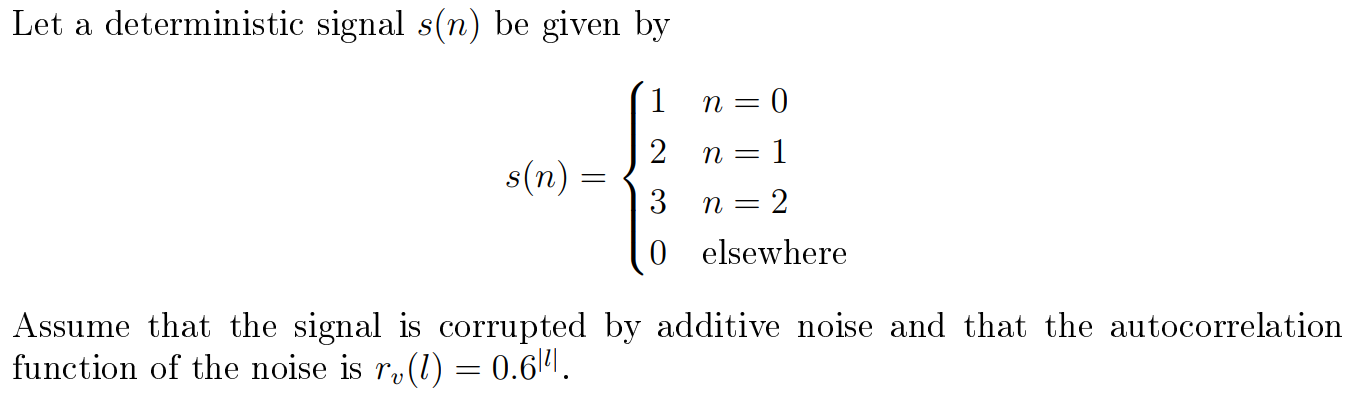

clear variables;

### 1) Determine the matched filter for detecting the presence of absense of the signal

The impulse response of the matched filter can be computed using Eq. 14.97:

        

where $k$ is the normalisation factor. Although the maximum SNR can be obtained by any choise of constant $\kappa$, we choose the constant by requiring that:

        

s = flip([1, 2, 3])';
p = numel(s);
ell = 0:p-1;
r_vv = 0.6.^abs(ell);
R_vv = toeplitz(r_vv)
% Compute normalisation factor
k = 1/sqrt(s'*(R_vv\s)) % Same as 1/sqrt(s'*inv(R_vv)*s)
% Compute the filter
h = k*(R_vv\s)

### 1a) Comment on the shape of the magnitude response

% Plot the magnitude response
figure('position', [0, 0, 800, 350])
[H_h, w_h] = freqz(h, 1);
plot(w_h/pi, 20*log10(abs(H_h)))
legend('Matched Filter')
xlabel('\omega/\pi')
ylabel('Magnitude Response (dB)')
grid on;

The matched filter passes DC components almost undistorted, has a small gain at midrange frequencies and attenuates high frequency components.

The reason for this shape is a trade-o�ff between 

- (A) the noise is centered at low frequencies, and

- (B) the signal that is also somewhat low-pass in nature as evident from the identical signs of all samples of� the signal.

Assume the noise process is an MA(q) process, the PSD can be computed using Eq. (13.119):

        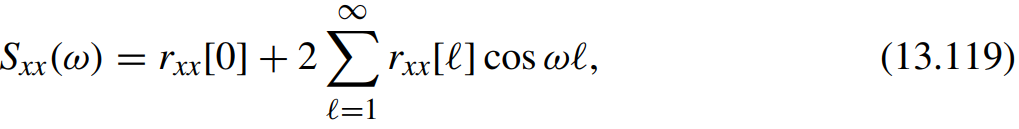

By plotting the PSD of the noise, we observe that the noise is centred at low frequencies. 

w = 0:0.001:pi;
S = r_vv(1);
for l = 2:numel(r_vv)
    S = S + 2 * r_vv(l)*cos(w*(l-1));
end

figure('position', [0, 0, 800, 350])
plot(w/pi, pow2db(S))
xlabel('\omega/\pi')
ylabel('S_{vv}(\omega) in dB')
clear figure;
grid on;

### 2) Calculate the optimum signal to noise ratio

The optimum SNR can be compute using Eq. 14.98:

        

Since the attenuation factor $a$ is not given in this problem, we assume $a=1$:

SNR_opt = s'*(R_vv\s)

### 3) Compute the SNR of a non-optimal filter

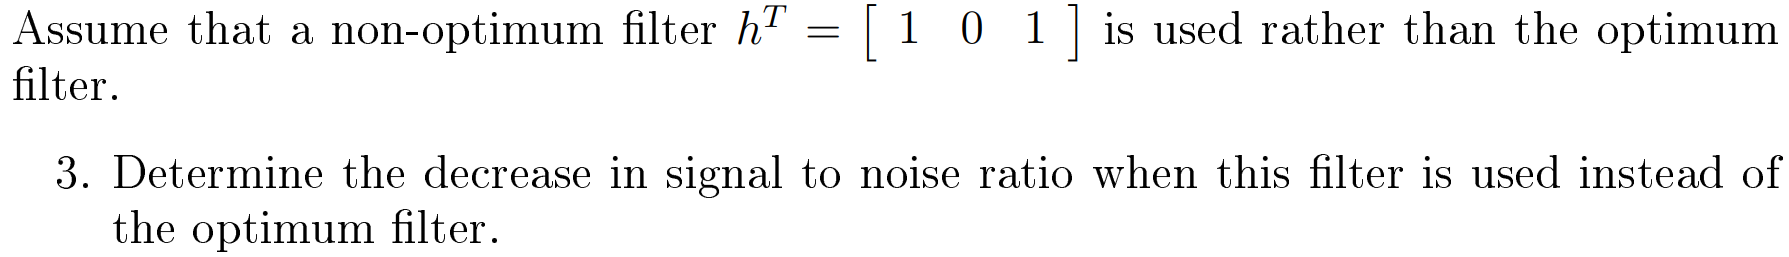

We can compute the SNR using Eq. (19.94):

        

h_nopt = [1, 0, 1]';
SNR_nopt = (h_nopt'*s)^2 / (h_nopt'*R_vv*h_nopt)

## Functions

function [S, w] = ar2psd(a, v, N)
% AR2PSD Compute the Power Spectral Density from AR(p) coefficients
%   [S, w] = ar2psd(a, v, N)
% a: AR(p) coefficients
% v: the variance
% N: number of points in the range [1, pi]
% S: the estimated power spectrum
% w: frequencies
    w = linspace(0, 1, N) * pi;
    
    % Compute the transfer function
    % Used Eq. (13.133) in the book
    H = ones(N, 1);
    for k=1:numel(a)
        H = H + a(k)*exp(-1j * w' * k);
    end
    H = 1./H;
    
    % Finally compute the PSD
    S = v * H.*conj(H);
end

function [h, SNR] = matched_filter(s, v, a)
% MATCHED_FILTER: Compute the impulse response of a matched filter and 
%                 and the corresponding output SNR.
%   [h, SNR] = matched_filter(s, v, a)
% s:   the signal
% v:   a realisation of the additive noise
% a:   the attenuation factor (default=1)
% h:   the impulse response of the matched filter
% SNR: the output SNR
    if nargin < 3
        a = 1;
    end

    p = numel(s); % Signal length
    
    % The autocorrelation matrix must be p x p since
    % its inverse is multiplied by a p-tap signal s(n)
    [r_vv, ~] = xcorr(v, p-1, 'biased');
    R_vv = toeplitz(r_vv(p:end));
    
    % The expression `R_vv^{-1} * s` is used multiple times,
    % so compute it once and reuse
    R_vv_inv_s = R_vv\s;
    
    % Compute normalisation factor
    k = 1/sqrt(s'*R_vv_inv_s);
    
    % Compute the filter
    h = k*R_vv_inv_s;
    
    % Compute the output SNR
    SNR = a^2 * s' * R_vv_inv_s;
end

function [x, v, s] = gen_noisy_signal(s_original, N, noise_var, D)
% Embeds a signal into a realisation of a WGN process
%  s_original: the original signal that needs to be embedded
%  N:          the number of samples of the noisy signal
%  noise_var:  the variance of WGN (default=1)
%  D:          the position of embedding
    if nargin < 4
        D = 0;
    end
    if nargin < 3
        noise_var = 1;
    end
    
    n = (1:N)';
    p = numel(s_original); % Signal length
    
    % Generate the signal.
    % Ensure that s[n] is zero when n is outside the interval [1, p]
    s = zeros(N, 1);
    s(n >= D+1 & n <= p+D) = s_original;
    
    % Generate the zero-mean WGN
    v = sqrt(noise_var) * randn(N, 1);
    
    % Generate the measured signal x[n]
    x = v + s;
end